clear
clc

# **Data analysis of the Student Robotics' holonomic robot simulation**

**to c**ompute the statistical analysis over the 

**Import and Processing of the gold distances matrix**

% Gold Dist Matrix example
load('ex_gold_dist.mat')
ex_gold_dist_cell = get_gold_dist(ex_gold_dist);

% Gold Dist Matrix

load('my_gold_dist.mat')
my_gold_dist_cell = get_gold_dist(my_gold_dist);

**Compute the averege distance between robot and gold tokens at every run**

% Gold Dist example

[ex_av_gold_dist, tot_av_ex_gl, ex_std_gl] = ...
    av_gold_dist(ex_gold_dist_cell, ex_gold_dist);

% My Gold Dist 

[my_av_gold_dist, tot_av_my_gl, my_std_gl] = ...
    av_gold_dist(my_gold_dist_cell,my_gold_dist);

**Plot of the Average distance of each run and the average over the whole experiment**

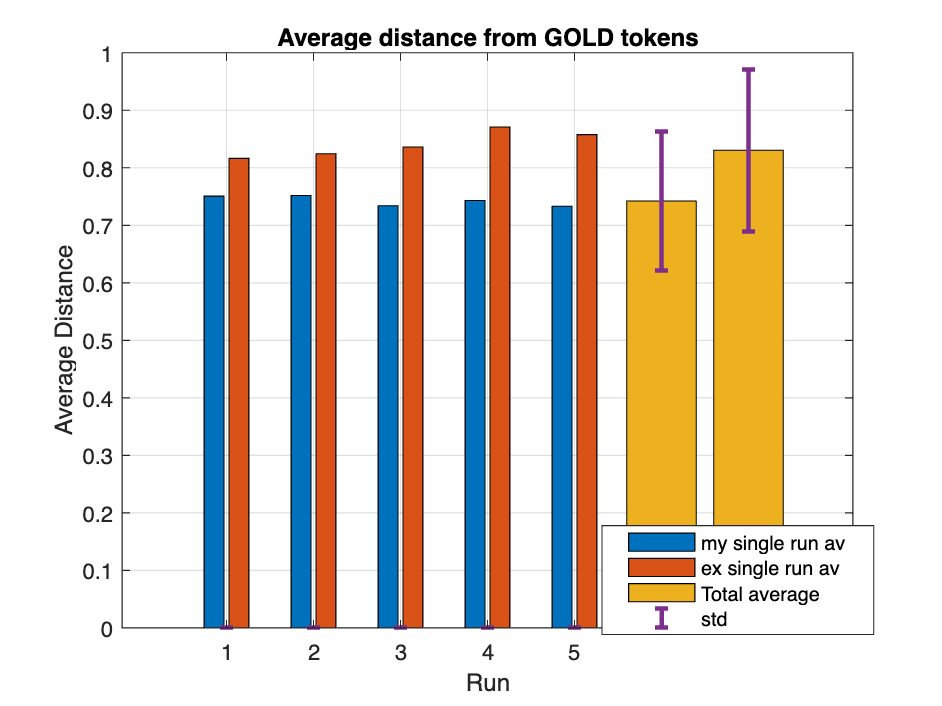

total_gold_dist = [my_av_gold_dist, ex_av_gold_dist];
figure

total_average_gold_dist = zeros(size(ex_av_gold_dist));
std_gold_dist = zeros(size(ex_av_gold_dist));

std_gold_dist(end + 1) = my_std_gl;
std_gold_dist(end + 1) = ex_std_gl;

total_average_gold_dist(end + 1) = tot_av_my_gl;
total_average_gold_dist(end + 1) = tot_av_ex_gl;
bar(total_gold_dist)
hold on
bar(total_average_gold_dist)
hold on 
errorbar(total_average_gold_dist,std_gold_dist ,'.', 'LineWidth',2)

grid on

legend('my single run av','ex single run av', 'Total average', 'std')
title('Average distance from GOLD tokens')
xlabel('Run')
ylabel('Average Distance')

legend("Position",[0.67345,0.13791,0.22,0.08])

**Violin Plot of the distance from obstacles**

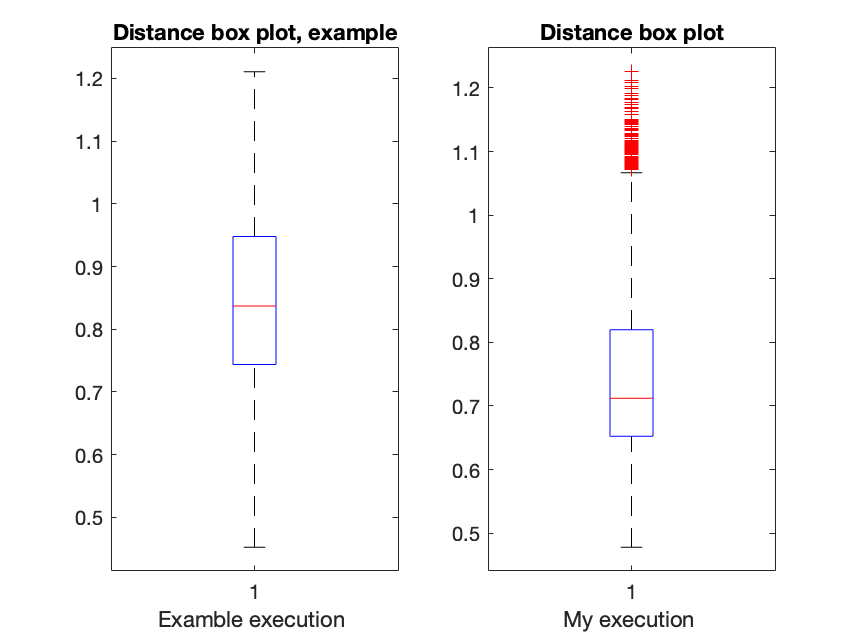

ex_gold_dist_plot = ex_gold_dist(find(ex_gold_dist~=20000));
ex_gold_dist_plot = ex_gold_dist_plot(find(ex_gold_dist_plot~=10000));

my_gold_dist_plot = my_gold_dist(find(my_gold_dist~=20000));
my_gold_dist_plot = my_gold_dist_plot(find(my_gold_dist_plot~=10000));

figure
subplot(1,2,1);
boxplot(ex_gold_dist_plot);
title('Distance box plot, example')
xlabel("Examble execution ")
subplot(1,2,2);
boxplot(my_gold_dist_plot);
title('Distance box plot')
xlabel("My execution ")

Violin plots for the distances

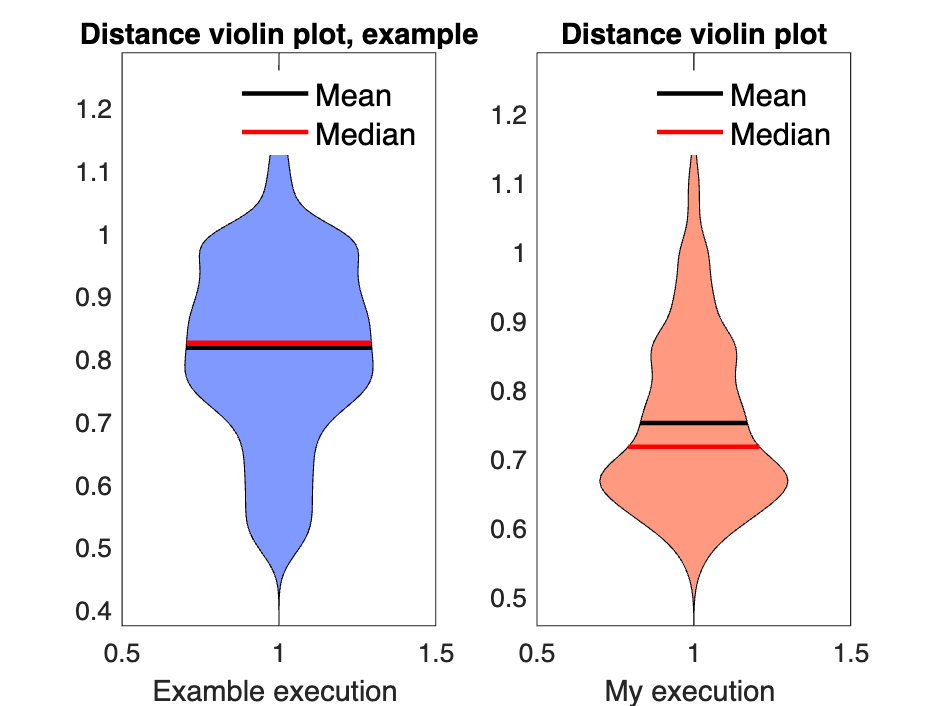


figure
subplot(1,2,1);
violin(ex_gold_dist_cell{1,1}','facecolor',[0,0.2,1]);
title('Distance violin plot, example')
xlabel("Examble execution ")
subplot(1,2,2);
violin(my_gold_dist_cell{1,1}','facecolor',[1 0.2 0]);
title('Distance violin plot')
xlabel("My execution ")

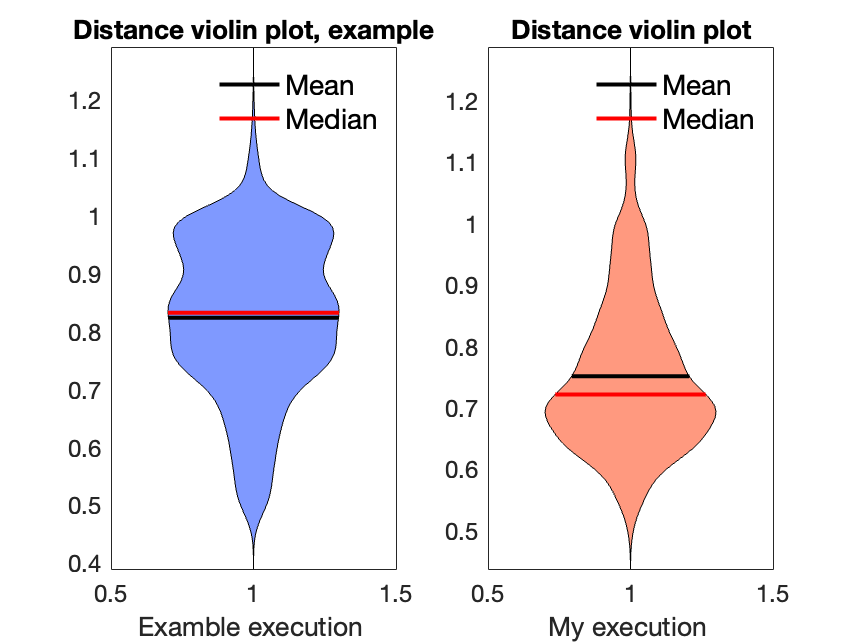


figure
subplot(1,2,1);
violin(ex_gold_dist_cell{1,2}','facecolor',[0,0.2,1]);
title('Distance violin plot, example')
xlabel("Examble execution ")
subplot(1,2,2);
violin(my_gold_dist_cell{1,2}','facecolor',[1 0.2 0]);
title('Distance violin plot')
xlabel("My execution ")

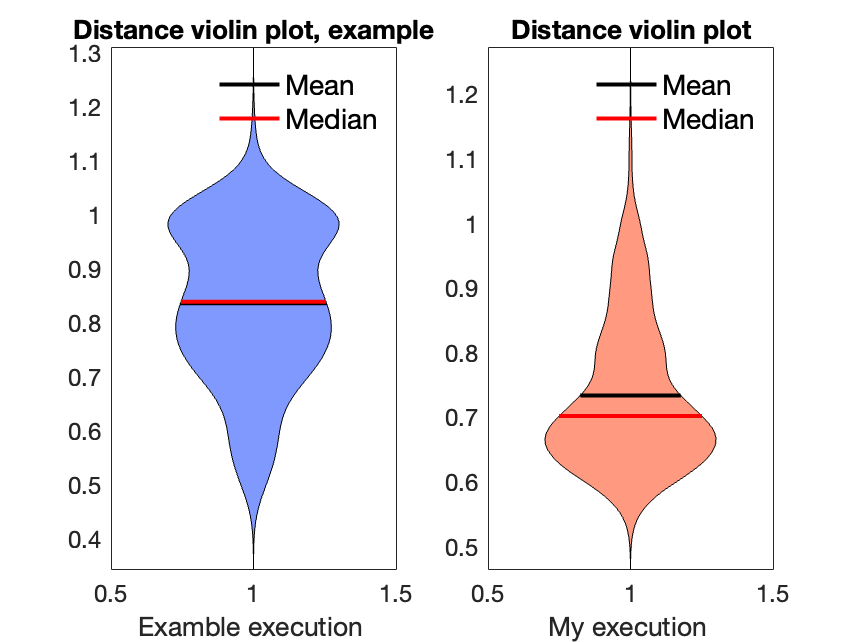


figure
subplot(1,2,1);
violin(ex_gold_dist_cell{1,3}','facecolor',[0,0.2,1]);
title('Distance violin plot, example')
xlabel("Examble execution ")
subplot(1,2,2);
violin(my_gold_dist_cell{1,3}','facecolor',[1 0.2 0]);
title('Distance violin plot')
xlabel("My execution ")

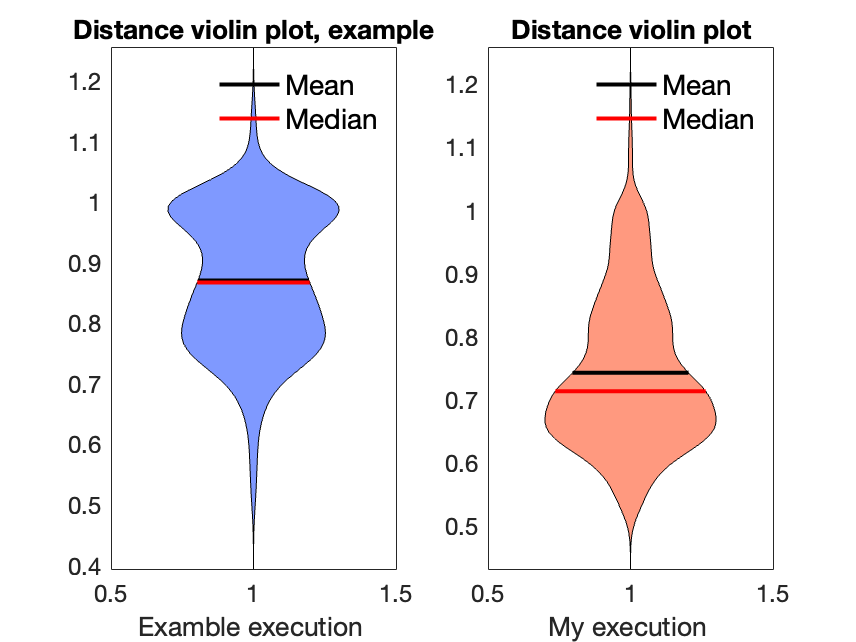


figure
subplot(1,2,1);
violin(ex_gold_dist_cell{1,4}','facecolor',[0,0.2,1]);
title('Distance violin plot, example')
xlabel("Examble execution ")
subplot(1,2,2);
violin(my_gold_dist_cell{1,4}','facecolor',[1 0.2 0]);
title('Distance violin plot')
xlabel("My execution ")

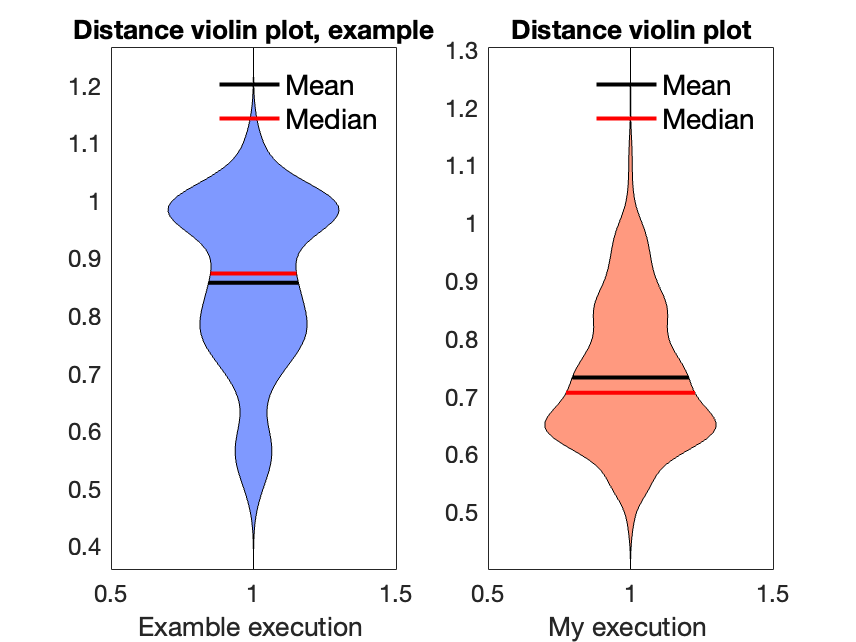


figure
subplot(1,2,1);
violin(ex_gold_dist_cell{1,5}','facecolor',[0,0.2,1]);
title('Distance violin plot, example')
xlabel("Examble execution ")
subplot(1,2,2);
violin(my_gold_dist_cell{1,5}','facecolor',[1 0.2 0]);
title('Distance violin plot')
xlabel("My execution ")

**Import and Processing of the gold distances matrix**

% laps time matrix example
load('ex_lap_time.mat')
ex_lap_time_cell = get_gold_dist(ex_lap_time);

% laps time matrix

load('my_lap_time.mat')
my_lap_time_cell = get_gold_dist(my_lap_time);

[ex_av_lap_time, tot_av_ex_lap_time, ex_std_lap_time] = ...
    av_gold_dist(ex_lap_time_cell, ex_lap_time);

[my_av_lap_time, tot_av_my_lap_time, my_std_lap_time] = ...
    av_gold_dist(my_lap_time_cell, my_lap_time);

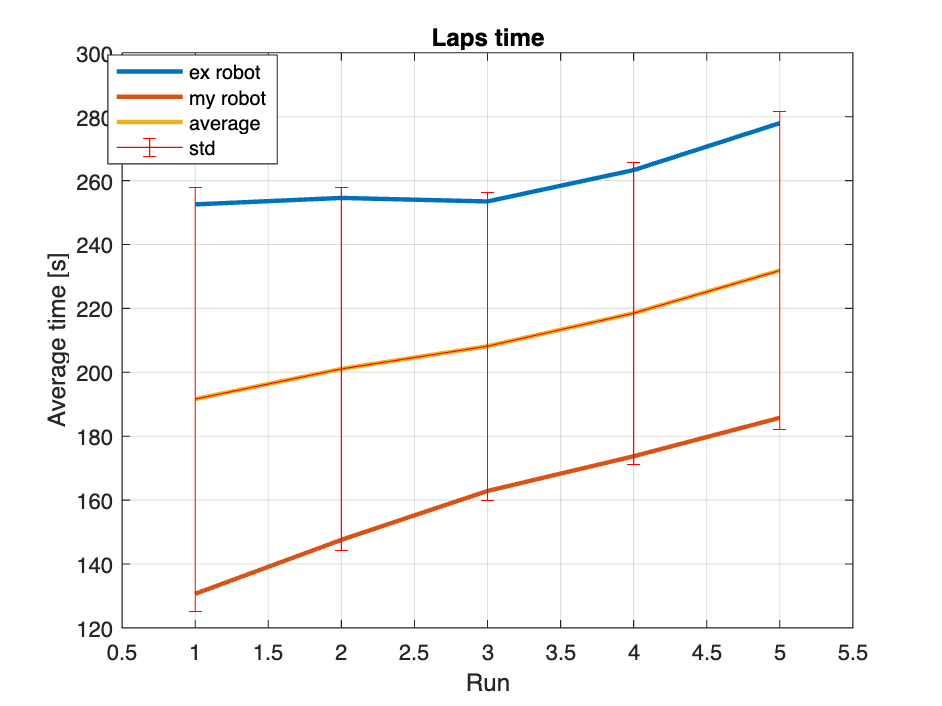


[lap_time_average,lap_time_std] = total_lap_time_average(ex_lap_time_cell, my_lap_time_cell);

figure 
plot(ex_av_lap_time,'LineWidth',2)
hold on

plot(my_av_lap_time,'LineWidth',2)
hold on

plot(lap_time_average,'LineWidth',2)
hold on 

errorbar(lap_time_average, lap_time_std,'r')
grid on

legend('ex robot','my robot', 'average', 'std')
title('Laps time')
xlabel('Run')
ylabel('Average time [s]')
xlim([0.5,5.5])

legend("Position",[0.14,0.8,0.13,0.09])

% laps time matrix example
load('ex_gold_hit.mat')

% laps time matrix

load('my_gold_hit.mat')

total_gold_hit = [ex_gold_hit,my_gold_hit];

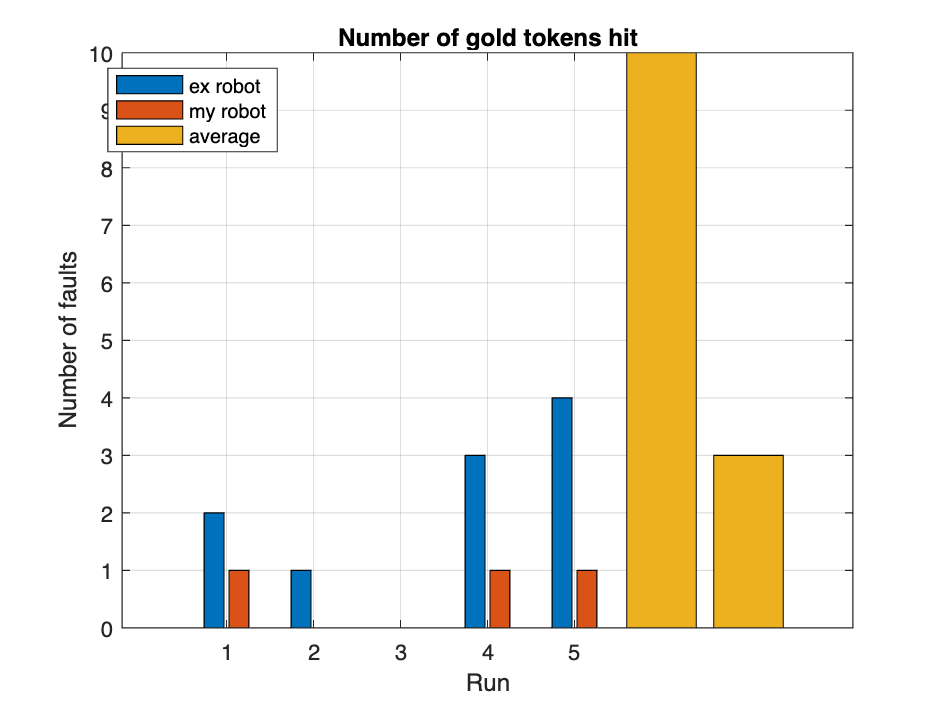

total_sum_gold_hit = zeros(size(ex_gold_hit));

tot_g_h_s = sum(total_gold_hit);

total_sum_gold_hit(end + 1) = tot_g_h_s(1,1);
total_sum_gold_hit(end + 1) = tot_g_h_s(1,2);
figure 
bar(total_gold_hit)
hold on
bar(total_sum_gold_hit)
legend('ex robot','my robot', 'average')
title('Number of gold tokens hit')
xlabel('Run')
ylabel('Number of faults')

legend("Position",[0.14,0.8,0.13,0.09])
grid on

**10 laps on 3 different maps (7-tokens) paired T-test**

% Gold Dist Matrix example
load('ex_gold_dist_2.mat')


[ex_laps_gold_dist_cell]= get_laps(ex_gold_dist_2);
ex_laps_gold_dist_av =get_laps_av(ex_laps_gold_dist_cell);

% Gold Dist Matrix

load('my_gold_dist_2.mat')

[my_laps_gold_dist_cell]= get_laps(my_gold_dist_2);
my_laps_gold_dist_av =get_laps_av(my_laps_gold_dist_cell);


**Lilliefors test, Cheking if the two populations are ither or not part of a normal population**

ans = 0

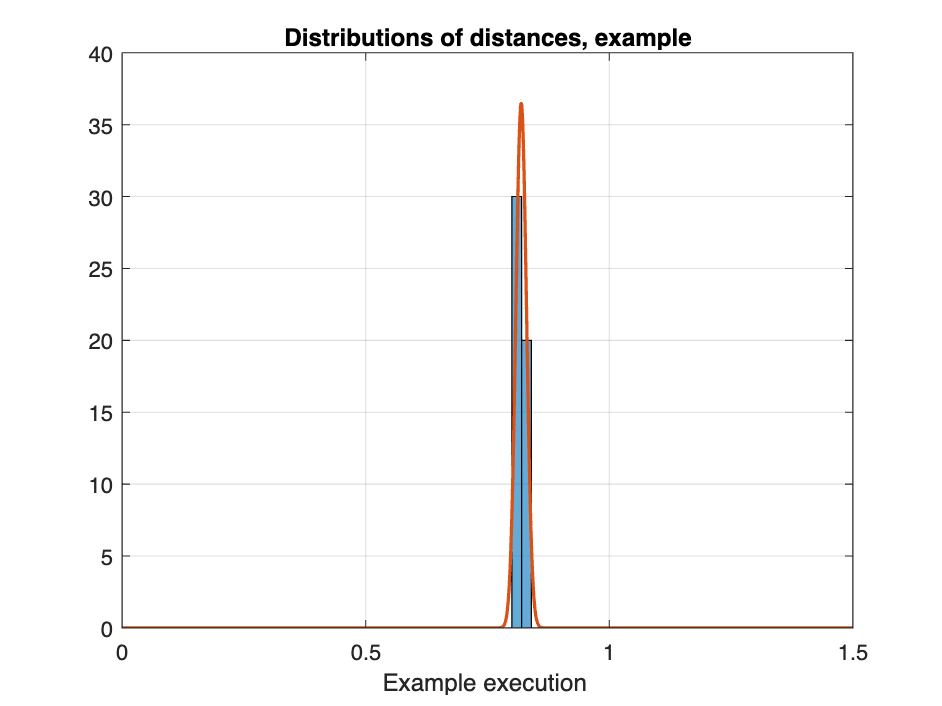

ans = 0

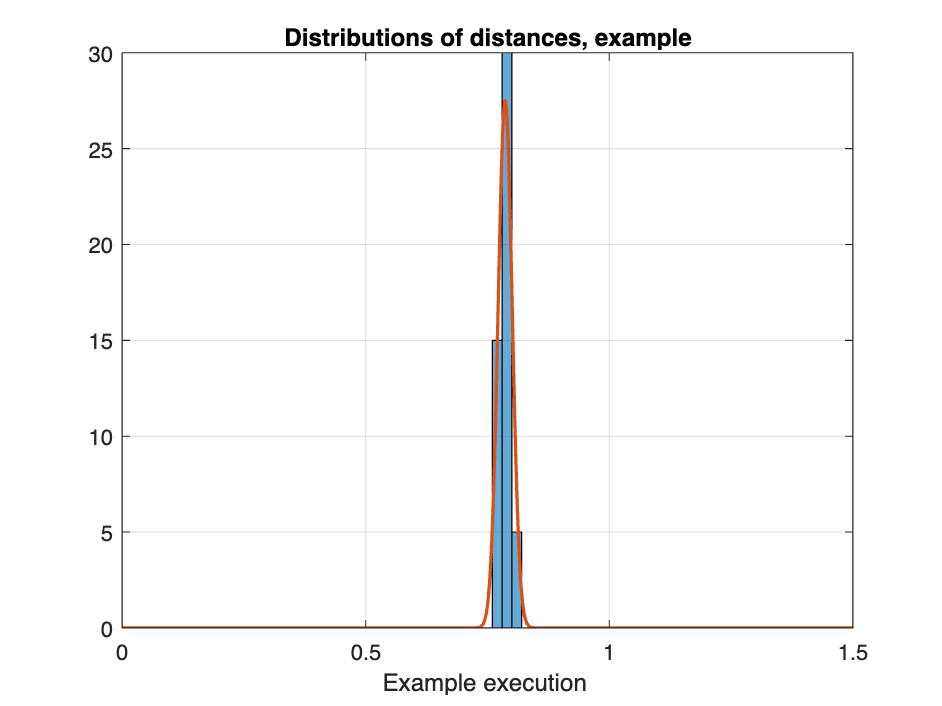

ans = 0

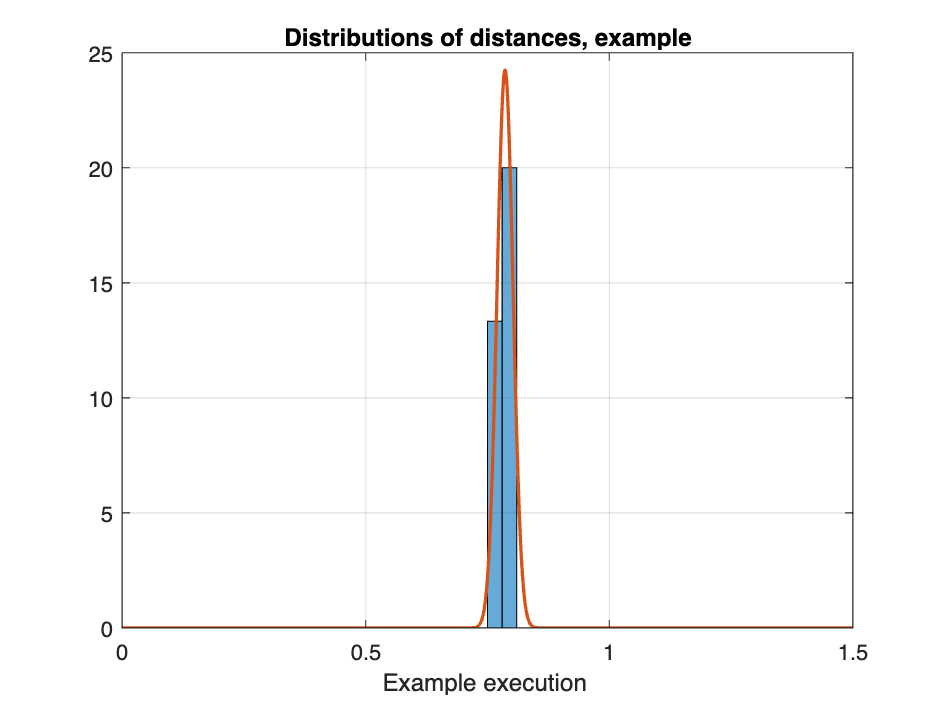

ans = 0

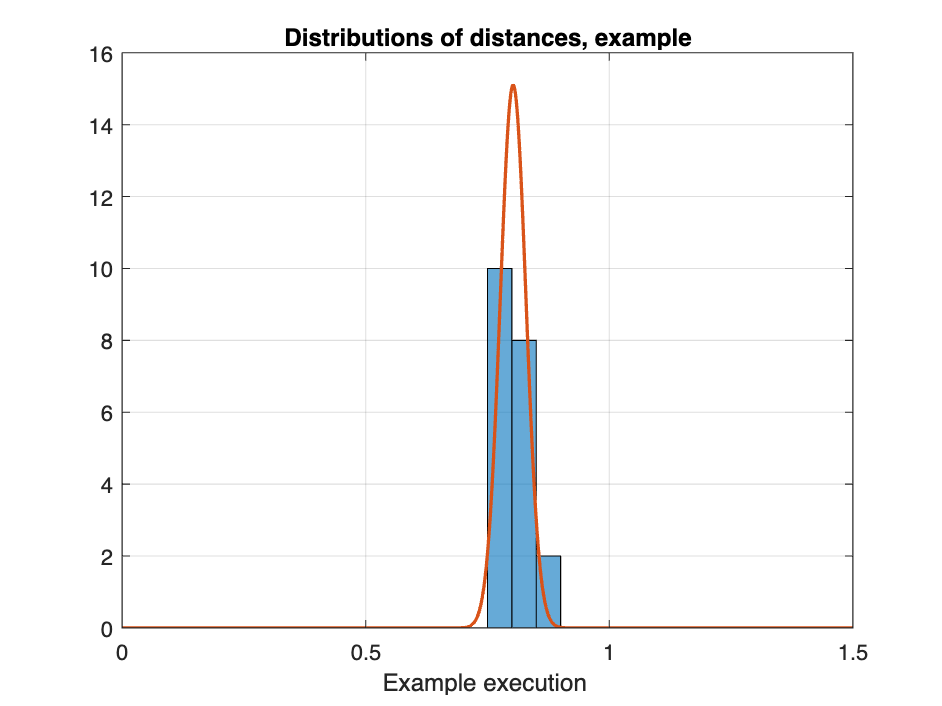

ans = 0

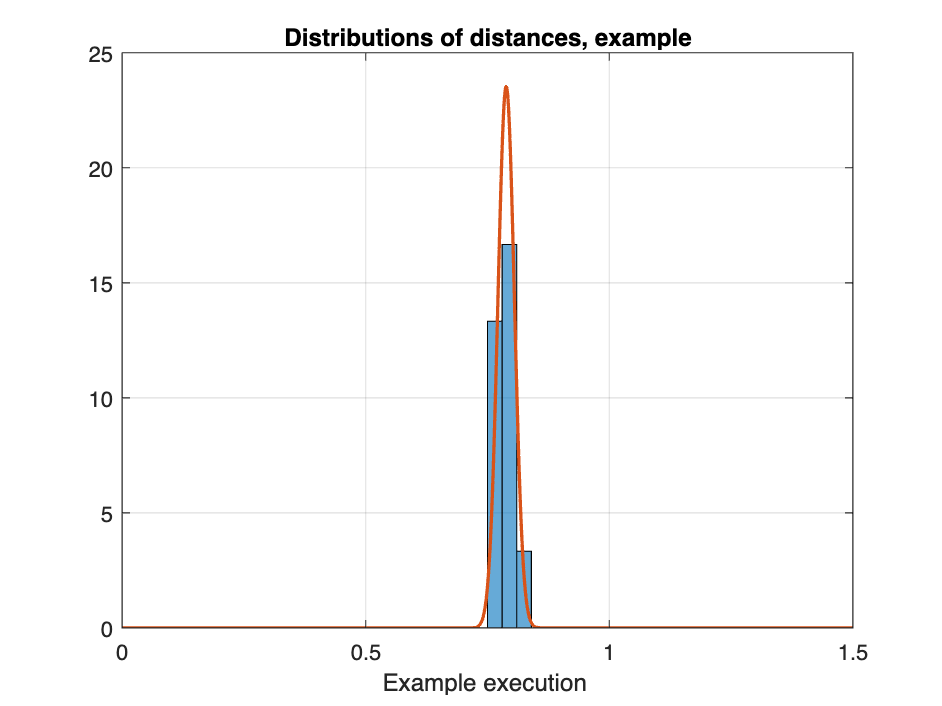

[~,s] = size(ex_laps_gold_dist_av);

for i = 1:s
    lillietest(ex_laps_gold_dist_av(:,i))

    figure
    histogram(ex_laps_gold_dist_av(:,i),'Normalization','pdf');
    title('Distributions of distances, example')
    xlabel("Example execution ")
    hold on
    y = 0:0.001:1.5;
    
    mu = mean(ex_laps_gold_dist_av(:,i));
    sigma = std(ex_laps_gold_dist_av(:,i));
    f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
    plot(y,f,'LineWidth',1.5)
    grid on

end 

ans = 0

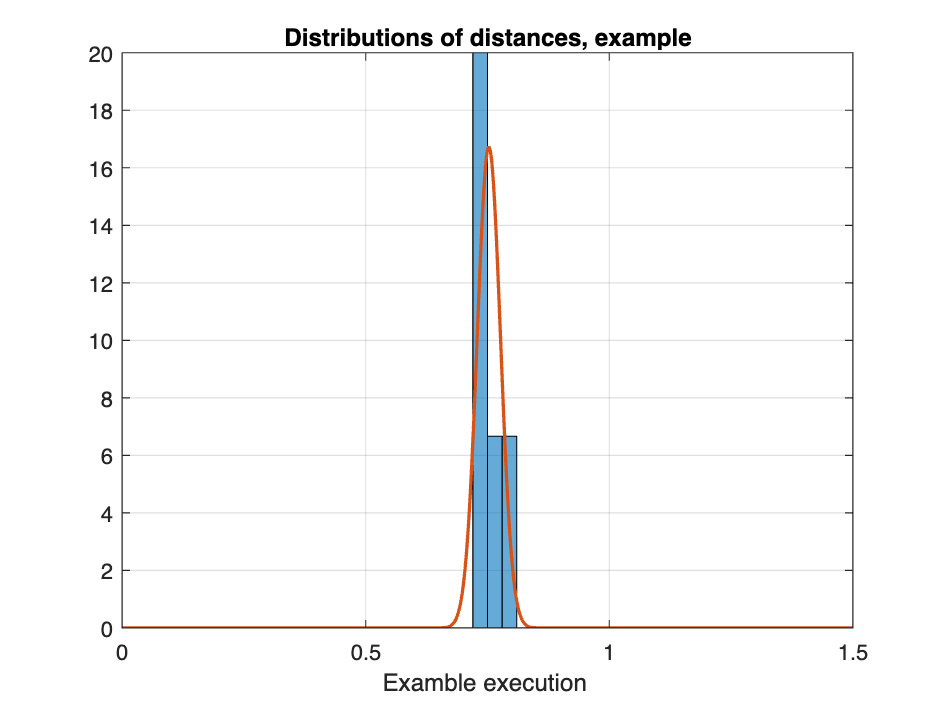

ans = 0

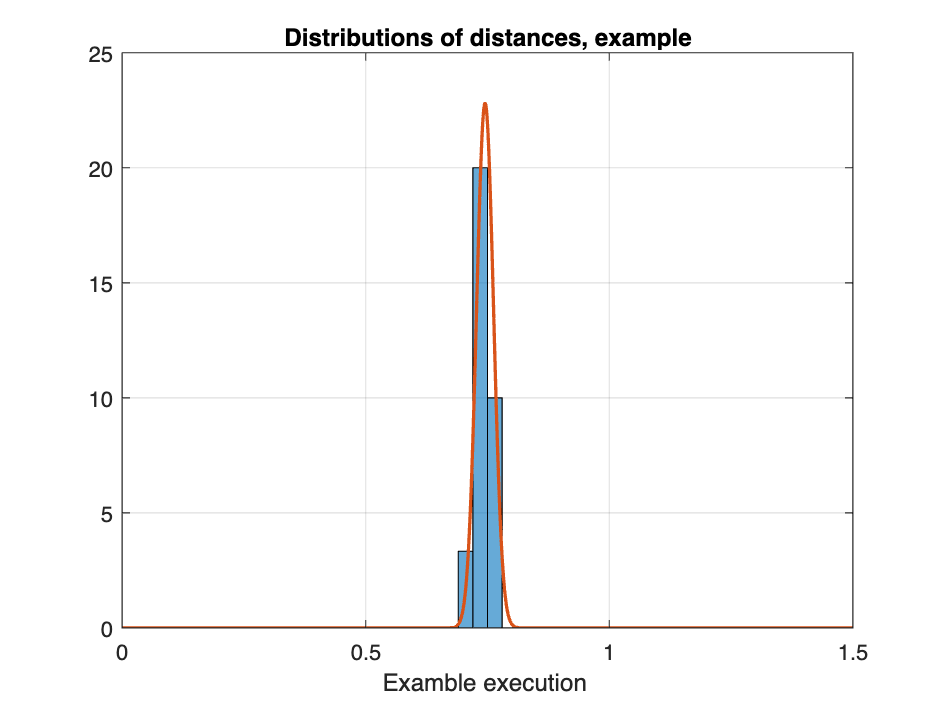

ans = 0

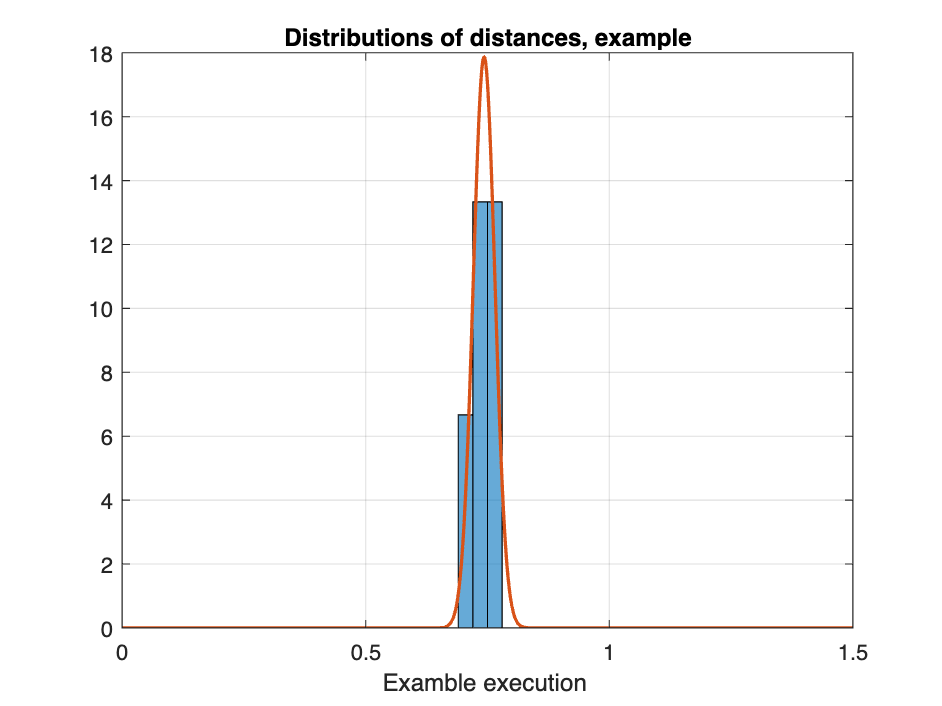

ans = 0

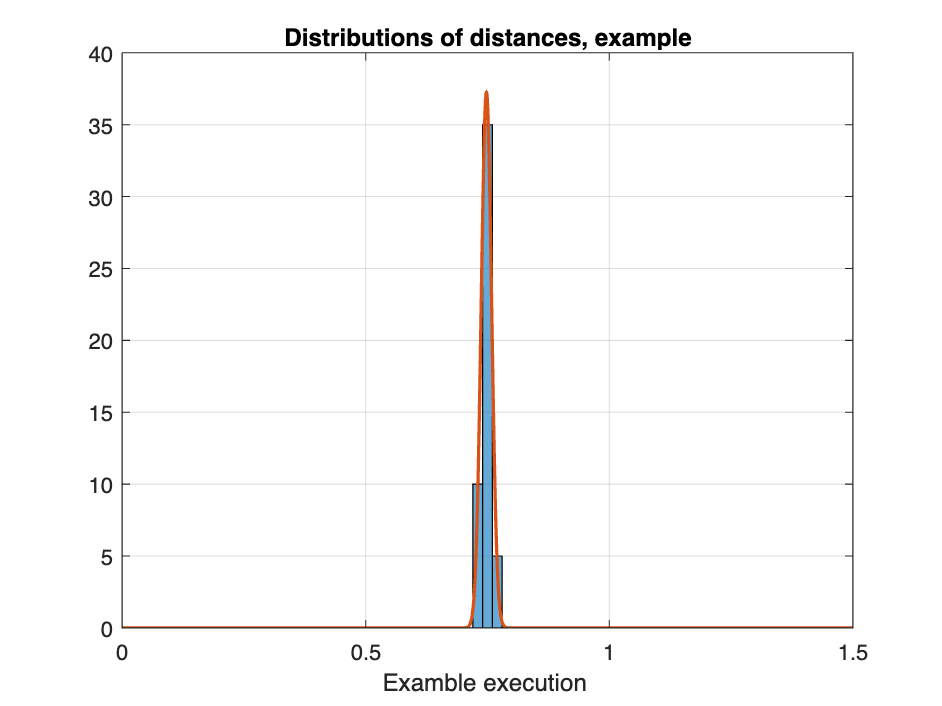

ans = 0

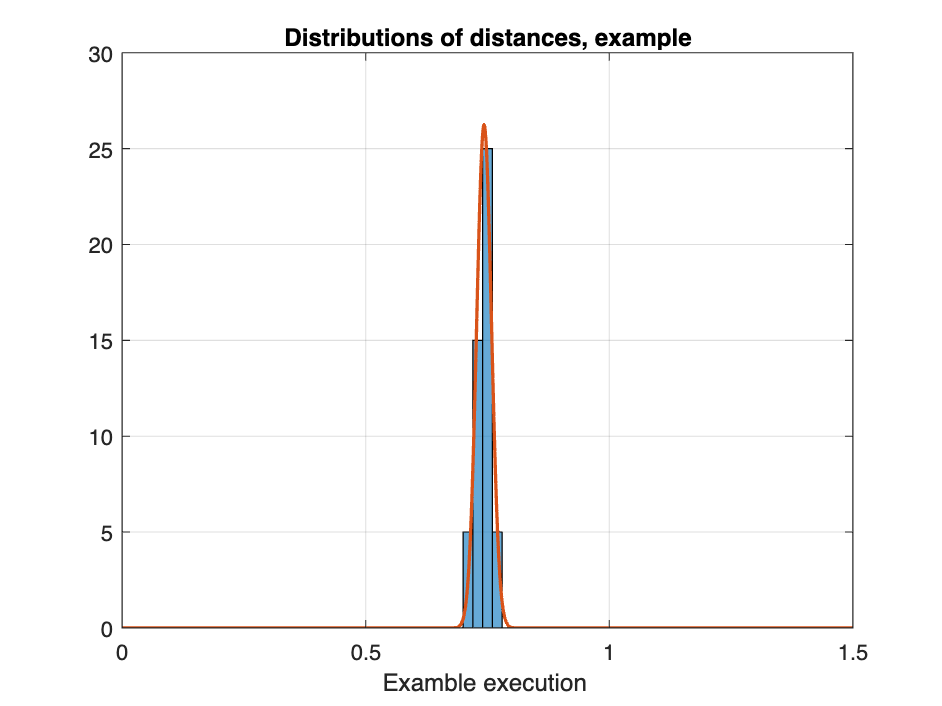


[~,s] = size(my_laps_gold_dist_av);


for i = 1:s
    lillietest(my_laps_gold_dist_av(:,i))

    figure
    histogram(my_laps_gold_dist_av(:,i),'Normalization','pdf');
    title('Distributions of distances')
    xlabel("Execution ")
    hold on
    y = 0:0.001:1.5;
    
    mu = mean(my_laps_gold_dist_av(:,i));
    sigma = std(my_laps_gold_dist_av(:,i));
    f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
    plot(y,f,'LineWidth',1.5)
    grid on

end 

**T-Test between the two population**

**First run: **

for i = 1:s
  [h,p,ci,stats] = ttest( my_laps_gold_dist_av(:,i), ex_laps_gold_dist_av(:,i),'Alpha',0.05,'Tail','left')
end 

h = 1

p = 1.6348e-06

ci =       -Inf
   -0.0544


stats = struct with fields:
    tstat: -10.1089
       df: 9
       sd: 0.0208


h = 1

p = 3.9517e-04

ci =       -Inf
   -0.0260


stats = struct with fields:
    tstat: -4.9509
       df: 9
       sd: 0.0264


h = 1

p = 0.0011

ci =       -Inf
   -0.0243


stats = struct with fields:
    tstat: -4.2107
       df: 9
       sd: 0.0323


h = 1

p = 2.1073e-04

ci =       -Inf
   -0.0363


stats = struct with fields:
    tstat: -5.4207
       df: 9
       sd: 0.0320


h = 1

p = 1.3826e-04

ci =       -Inf
   -0.0309


stats = struct with fields:
    tstat: -5.7494
       df: 9
       sd: 0.0250


% laps time matrix example
load('ex_lap_time_2.mat')
ex_lap_time_cell_2 = get_gold_dist(ex_lap_time_2);

% laps time matrix

load('my_lap_time_2.mat')
my_lap_time_cell_2 = get_gold_dist(myl_ap_time_2);

[ex_av_lap_time_2, tot_av_ex_lap_time_2, ex_std_lap_time_2] = ...
    av_gold_dist(ex_lap_time_cell_2, ex_lap_time_2);

[my_av_lap_time_2, tot_av_my_lap_time_2, my_std_lap_time_2] = ...
    av_gold_dist(my_lap_time_cell_2, myl_ap_time_2);

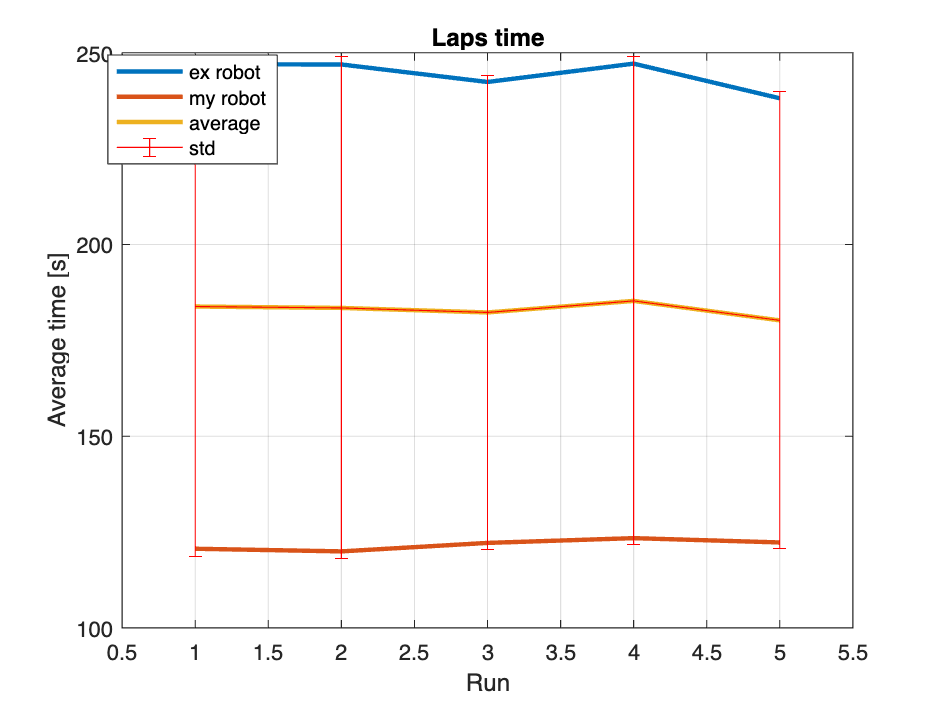


[lap_time_average_2,lap_time_std_2] = total_lap_time_average(ex_lap_time_cell_2, my_lap_time_cell_2);

figure 
plot(ex_av_lap_time_2,'LineWidth',2)
hold on

plot(my_av_lap_time_2,'LineWidth',2)
hold on

plot(lap_time_average_2,'LineWidth',2)
hold on 

errorbar(lap_time_average_2, lap_time_std_2,'r')
grid on

legend('ex robot','my robot', 'average', 'std')
title('Laps time')
xlabel('Run')
ylabel('Average time [s]')
xlim([0.5,5.5])

legend("Position",[0.14,0.8,0.13,0.09])


[h,p,ci,stats] = ttest2( ex_av_lap_time_2, my_av_lap_time_2,'Alpha',0.05,'Tail','both')

h = 1

p = 3.6242e-12

ci =   118.2576
  126.9994


stats = struct with fields:
    tstat: 64.6960
       df: 8
       sd: 2.9970
